# Dimensionering af en varmepumpe til kraftvarmeværk

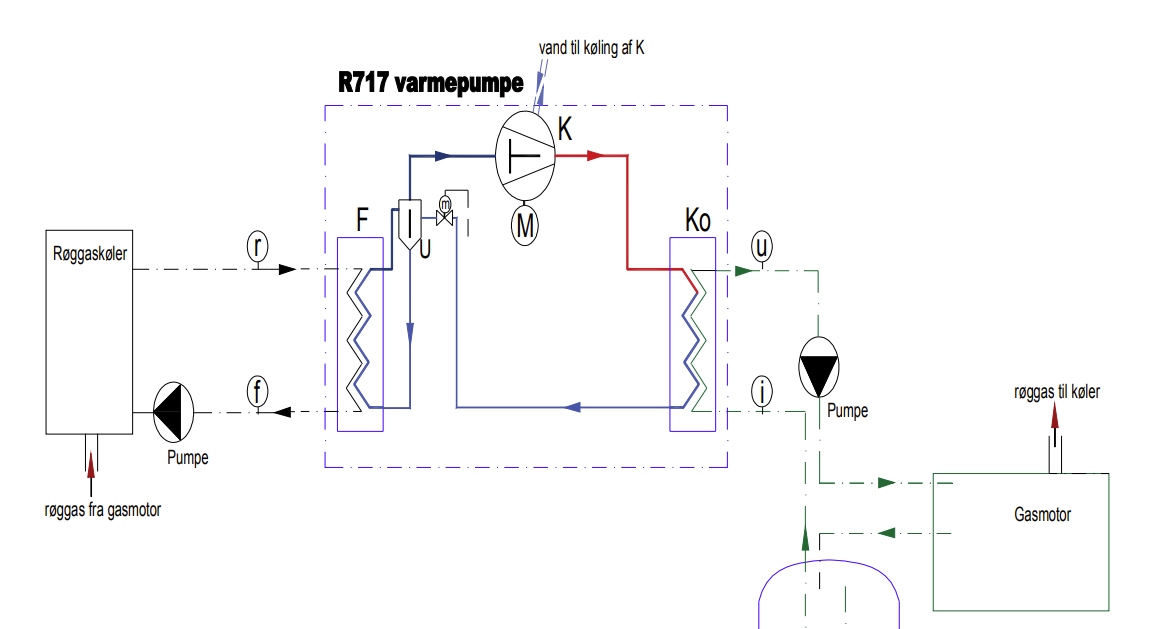

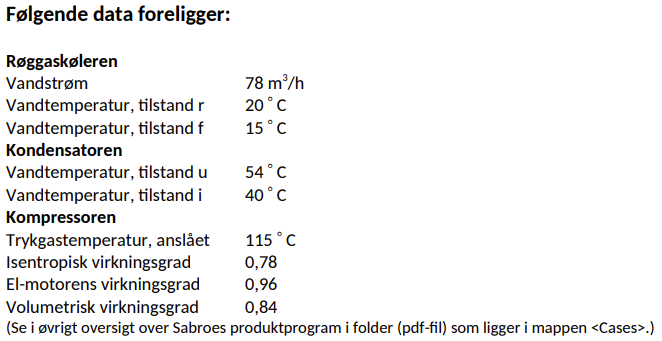

## Kompressorudgang sat til 115C

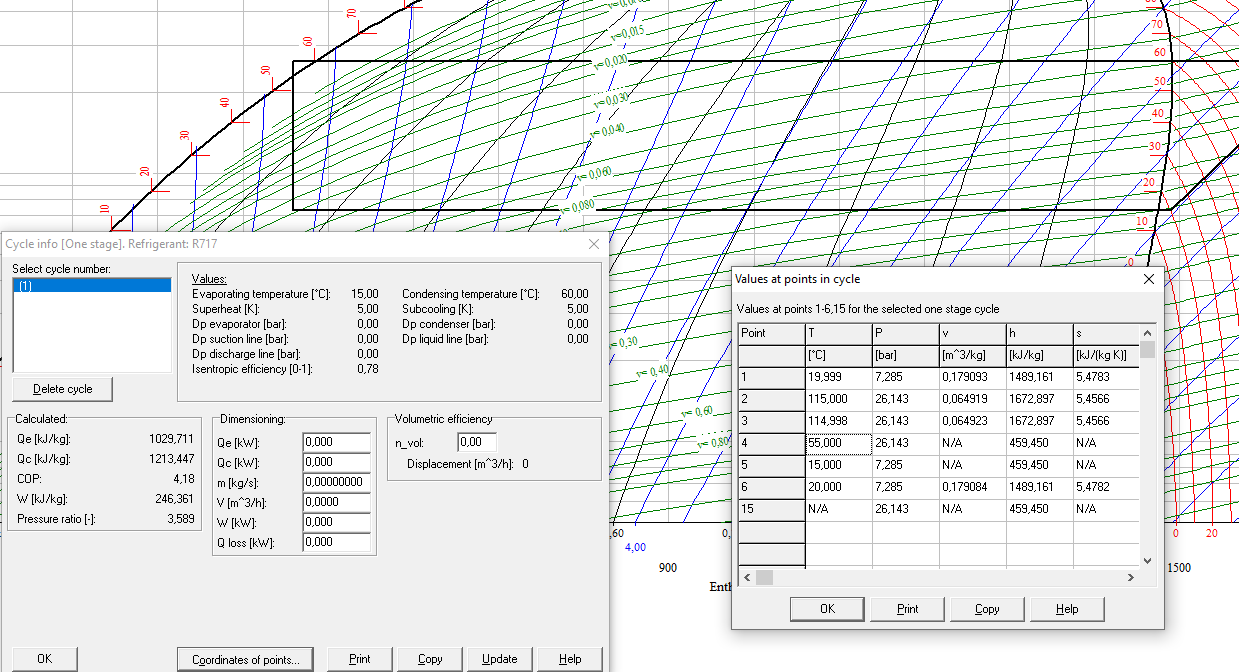

## Kompressorens faktiske udgangstemperatur

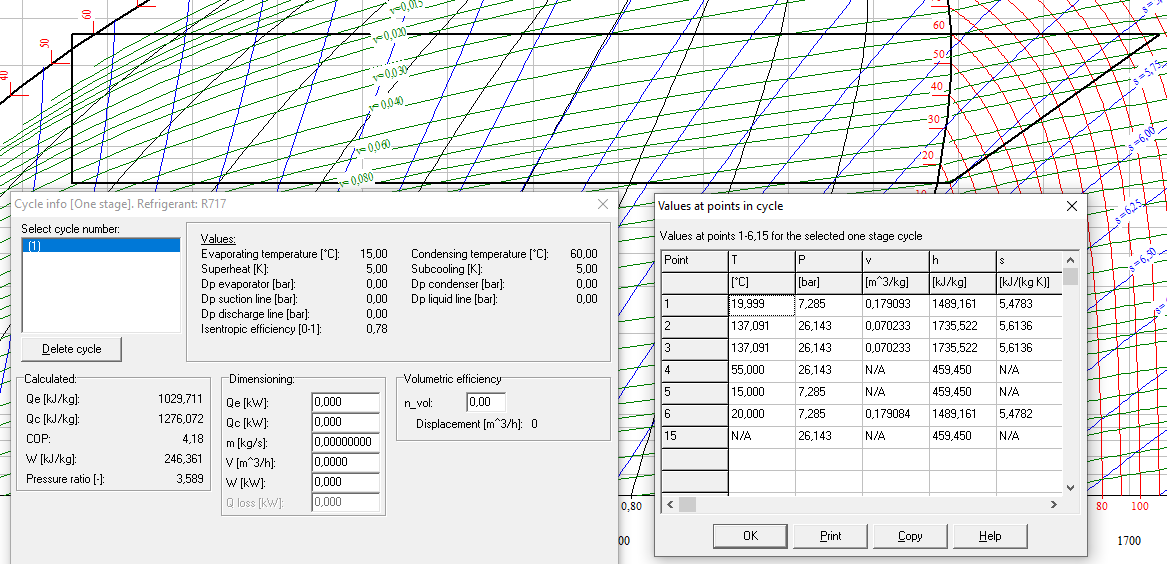

clc; clear;
u = symunit;


%----------------------------------------------%
%--------------- Røggaskøleren ----------------%
%----------------------------------------------%
q_V = 78 * u.m^3/u.h;
rho_V = 999.1 * u.kg/u.m^3;
cp_V = 4182 * u.J/(u.kg*u.K);

t_r = 20*u.K;
t_f = 15*u.K;

% Vores  Phi0
phi_RK = q_V*rho_V*cp_V*(t_r - t_f);
phi_RK = vpa(unitConvert(phi_RK, u.kW), 6)

$$phi\_RK = 452.642\,\mathrm{kW}$$

% Entalpier
% Kompressorudgang sat til 115C
h1 = 1489.161 *u.kJ/u.kg;
h2 = 1672.9*u.kJ/u.kg;
h3 = 459.45*u.kJ/u.kg;
h4 = h3;

% Kompressorudgangstemperatur ikke specificeret - fra det "faktiske"
% billede
h5 = 1735.522*u.kJ/u.kg; % ikke kølet kompressor


% Kondenseringspunkter, til udregning af kondensatorens 3 faser
super = 1491.49*u.kJ/u.kg;
konding = 485.03*u.kJ/u.kg;
subbing = 459.19*u.kJ/u.kg;

Phi0 = phi_RK;

% Massestrøm
q_mr = Phi0/(h1 - h4);
q_mr = vpa(unitConvert(q_mr, "SI"), 3)

$$q\_mr = 0.44\,\frac{\mathrm{kg}}{s}$$


% El-effekt
Pel = q_mr*(h5-h1);
Pel = vpa(unitConvert(Pel, u.kW), 6)

$$Pel = 108.296\,\mathrm{kW}$$

vpa(Pel*24*u.h, 3)

$$ans = 2600.0\,h\,\mathrm{kW}$$


% COP
COP = vpa(phi_RK/Pel, 3)

$$COP = 4.18$$


% Køling på kompressoren - 137C til 115C
phi_komp_cool = q_mr*(h5-h2);
phi_komp_cool = vpa(unitConvert(phi_komp_cool, u.kW),5) 

$$phi\_komp\_cool = 27.527\,\mathrm{kW}$$


% Vandstrøm omkring kompressor. Antagede ind og ud værdier
T_v_ind_komp = 18*u.K;
T_v_ud_komp = 70*u.K; % Det skal bruges til fjernvarme og skulle gerne være samme temp som det der kommer ned i akk. tanken

syms qV_vand

rho_V = 999.1 * u.kg/u.m^3;
cp_V = 4182 * u.J/(u.kg*u.K);

eq = phi_komp_cool == qV_vand*rho_V*cp_V*(T_v_ud_komp - T_v_ind_komp);

qV_vand = solve(eq, qV_vand);
qV_vand = vpa(unitConvert(qV_vand, u.m^3/u.h),6)

$$qV\_vand = 0.456113\,\frac{m^{3}}{h}$$



%-------------------------------%
%---------- Effekter -----------%
%-------------------------------%
% Henover kompressor
kompressor = vpa(unitConvert(q_mr*(h1-h2), u.kW), 4)

$$kompressor = -80.77\,\mathrm{kW}$$


% Henover kondensator
kondensator = vpa(unitConvert(q_mr*(h2-h3), u.kW), 6)

$$kondensator = 533.411\,\mathrm{kW}$$


kond_desuper = vpa(unitConvert(q_mr*(h2-super), u.kW), 6)

$$kond\_desuper = 79.7445\,\mathrm{kW}$$

kond_konding = vpa(unitConvert(q_mr*(super-konding), u.kW), 6)

$$kond\_konding = 442.422\,\mathrm{kW}$$

kond_subbing = vpa(unitConvert(q_mr*(konding - subbing), u.kW), 6)

$$kond\_subbing = 11.3588\,\mathrm{kW}$$


kond_total = vpa(kond_desuper+kond_konding+kond_subbing, 6)

$$kond\_total = 533.525\,\mathrm{kW}$$


% Ekspansionsventil
epv = vpa(unitConvert(q_mr*(h3-h4), u.kW), 4)

$$epv = 0.0$$


% Fordamper
% Det ses det stemmer overens med den indledende beregning af Phi0
fordamper = vpa(unitConvert(q_mr*(h4-h1), u.kW), 4)

$$fordamper = -452.6\,\mathrm{kW}$$



% Beregning af nødvendig slagvolumen, til dimensionering af varmepumpe
t_nh3_ind = 115*u.K;
t_nh3_ud = 60*u.K;


cp_NH3 = 2.881 * u.kJ/(u.kg*u.K);
rho_NH3 = 15.47 * u.kg/u.m^3;

eta_v = 0.84;
%q_Vs_komp = 2000 * u.m^3/u.h; % Valgt ud fra casen
syms q_Vs_komp

qV_NH3 = eta_v * q_Vs_komp;
qV_NH3 = vpa(unitConvert(qV_NH3, u.m^3/u.h), 3);

eq = kondensator == qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_nh3_ud);


q_Vs_komp = solve(eq, q_Vs_komp);
q_Vs_komp = vpa(unitConvert(q_Vs_komp, u.m^3/u.h), 3)

$$q\_Vs\_komp = 933.0\,\frac{m^{3}}{h}$$


% Volumenstrøm af vand i kondensator
t_kond_vi = 40 * u.K;
t_kond_vu = 54 * u.K;

syms qV_vand_kond
phi_kond_vand = qV_vand_kond*rho_V*cp_V*(t_kond_vu - t_kond_vi);

eq = kondensator == phi_kond_vand;

qV_vand_kond = solve(eq, qV_vand_kond);
qV_vand_kond = vpa(unitConvert(qV_vand_kond, u.m^3/u.h), 3)

$$qV\_vand\_kond = 32.8\,\frac{m^{3}}{h}$$

## Rørdimensioner

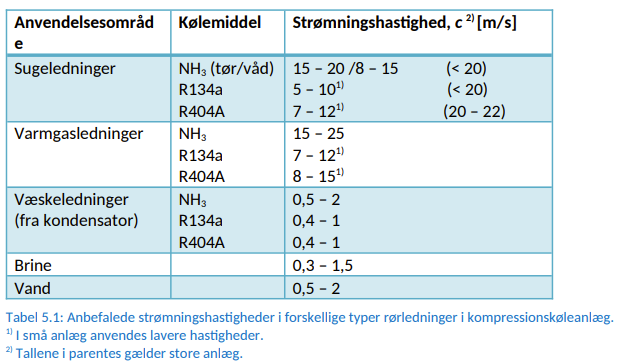

% Sugeledninger til kondensator
c1 = 17.5 * u.m/u.s;
NH3_ind = q_Vs_komp;

A1 = NH3_ind/c1;
A1 = vpa(unitConvert(A1, "SI"), 3);
A1 = vpa(unitConvert(A1, u.cm^2), 3)

$$A1 = 148.0\,{\mathrm{cm}}^{2}$$


cA1 = vpa(sqrt(A1/pi)*2, 3)

$$cA1 = 13.7\,\mathrm{cm}$$


%A = (D/2)^2*pi
%D = sqrt(A/pi)*2


% Varmgasledninger
c2 = 20 * u.m/u.s;
NH3_ind = q_Vs_komp;

A2 = NH3_ind/c2;
A2 = vpa(unitConvert(A2, "SI"), 3);
A2 = vpa(unitConvert(A2, u.cm^2), 3)

$$A2 = 130.0\,{\mathrm{cm}}^{2}$$


cA2 = vpa(sqrt(A2/pi)*2, 3)

$$cA2 = 12.8\,\mathrm{cm}$$


% Væskeledninger fra kondensator efter EPV
c3 = 1.25 * u.m/u.s;

NH3_ind = q_Vs_komp;

A3 = NH3_ind/c3;
A3 = vpa(unitConvert(A3, "SI"), 3);
A3 = vpa(unitConvert(A3, u.cm^2), 3)

$$A3 = 2070.0\,{\mathrm{cm}}^{2}$$


cA3 = vpa(sqrt(A3/pi)*2, 3)

$$cA3 = 51.4\,\mathrm{cm}$$